% A script used to 1. simulate how to draw samples from Poisson, Bernoulli,
% multi-Bernoulli and multi-Bernoulli mixture RFSs with possible uniform,
% Gaussian or Gaussian mixture spatial distribution. 2. draw samples from 
% RFS of objects (dynamic equations) to simulate object trajectories. 3.
% simulate object trajectories
close all; clear; clc

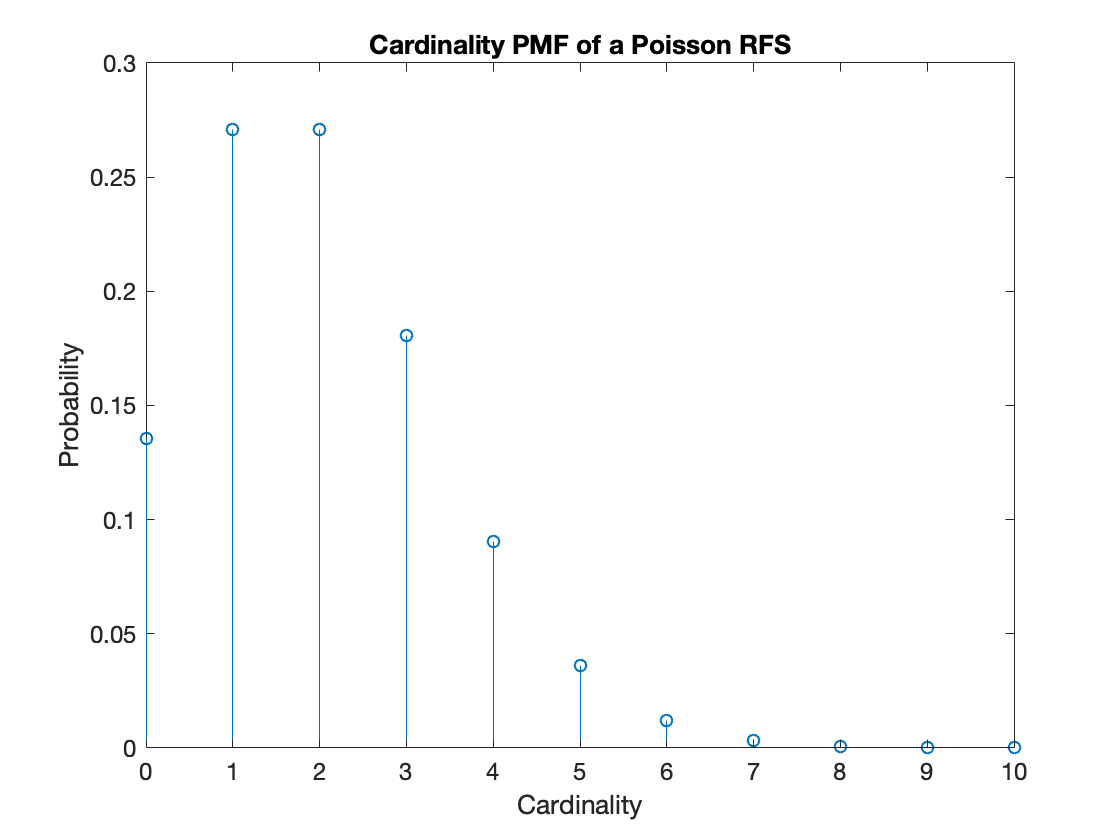

%% uniform distribution
%inputArg1{i} specifies the interval of a uniform distribution, a d-by-2
%matrix, where d is the dimension. The interval of the ith dimension is
%from interval(i,1) to interval(i,2).
clear

RFS = multiobjectProcess();

%Poisson RFS
%2D 
inputArg1{1} = [-1 1;-1 1];

RFS = spatialDistribution(RFS,inputArg1);
lambda = 2;
[RFS, PoissonInstance] = PoissonRFSs(RFS,lambda);
cardStemPlot(RFS, 0:10);

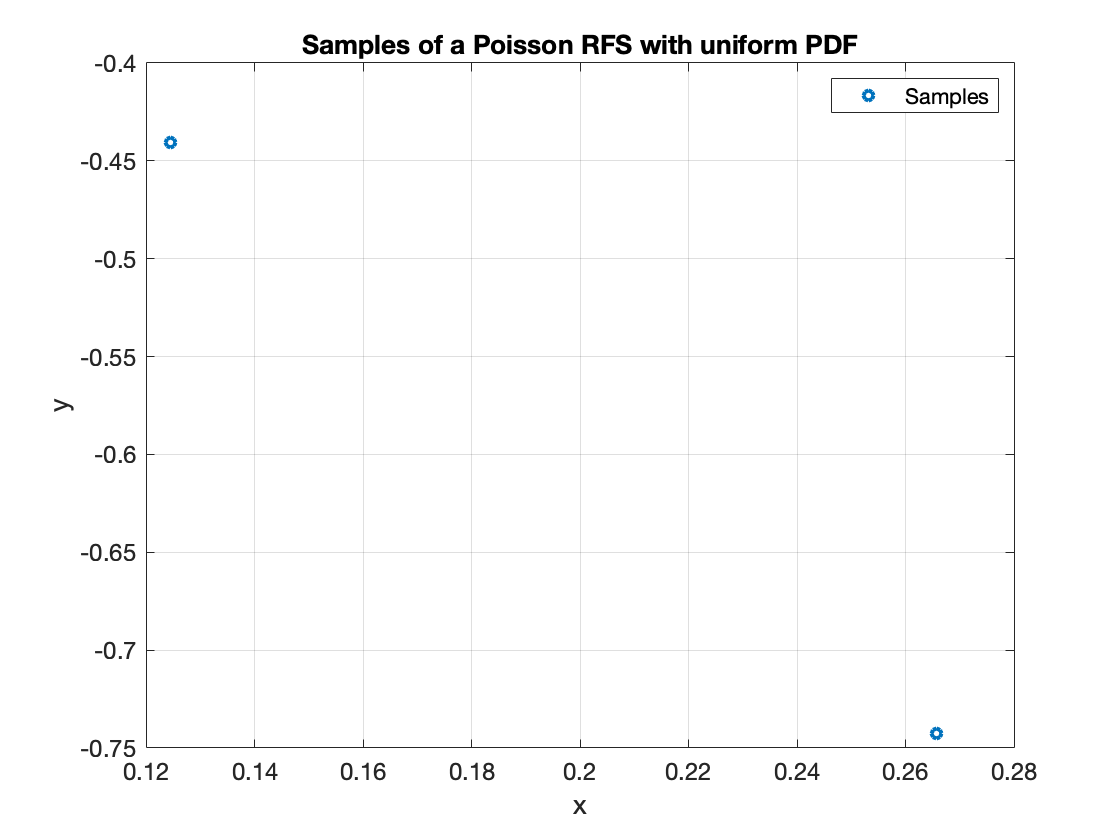

instance2Dplot(RFS,PoissonInstance);

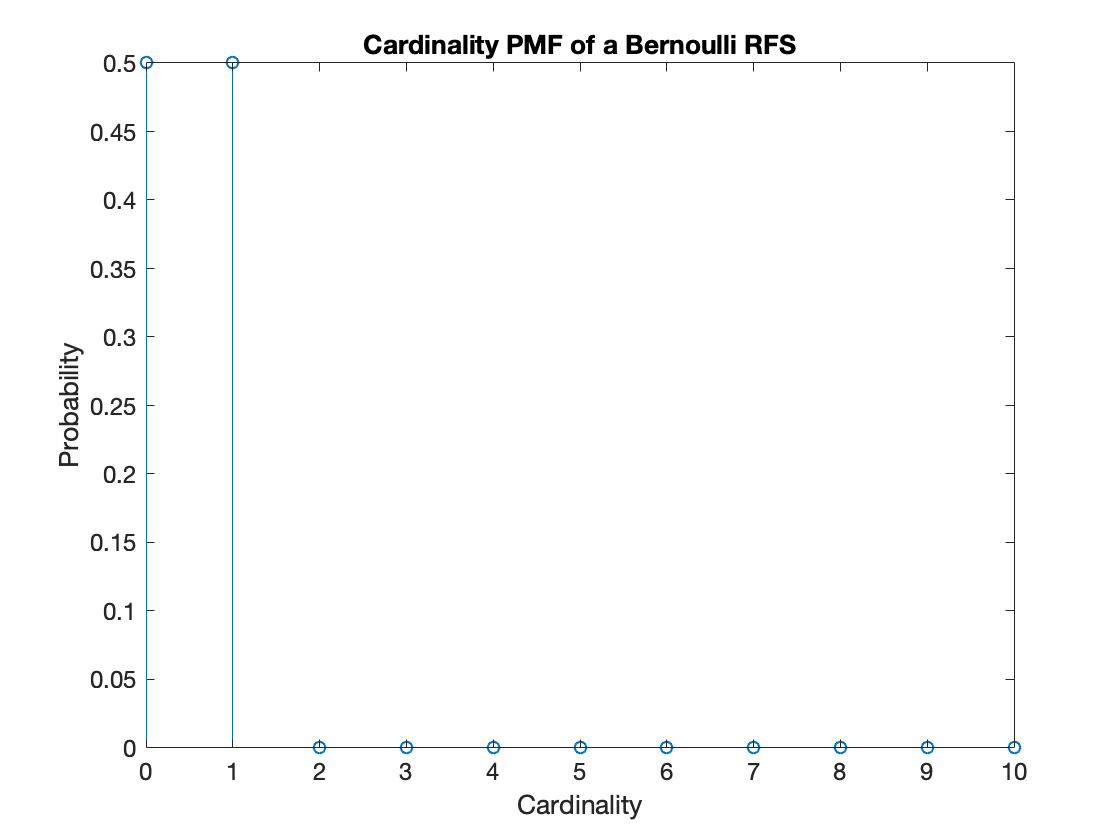


%Bernoulli RFS
%2D
inputArg1{1} = [-1 1;-1 1];

RFS = spatialDistribution(RFS,inputArg1);
r = 0.5;
[RFS, BernoulliInstance] = BernoulliRFSs(RFS,r);
cardStemPlot(RFS, 0:10);

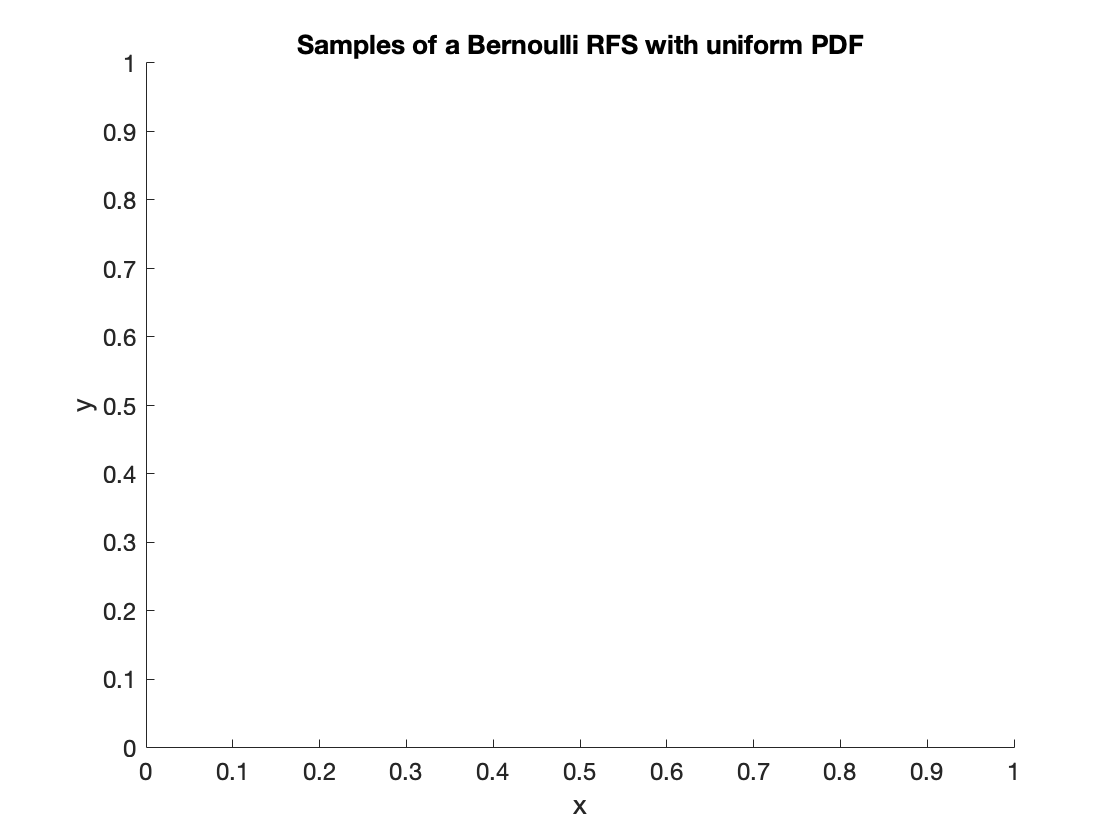

instance2Dplot(RFS,BernoulliInstance);

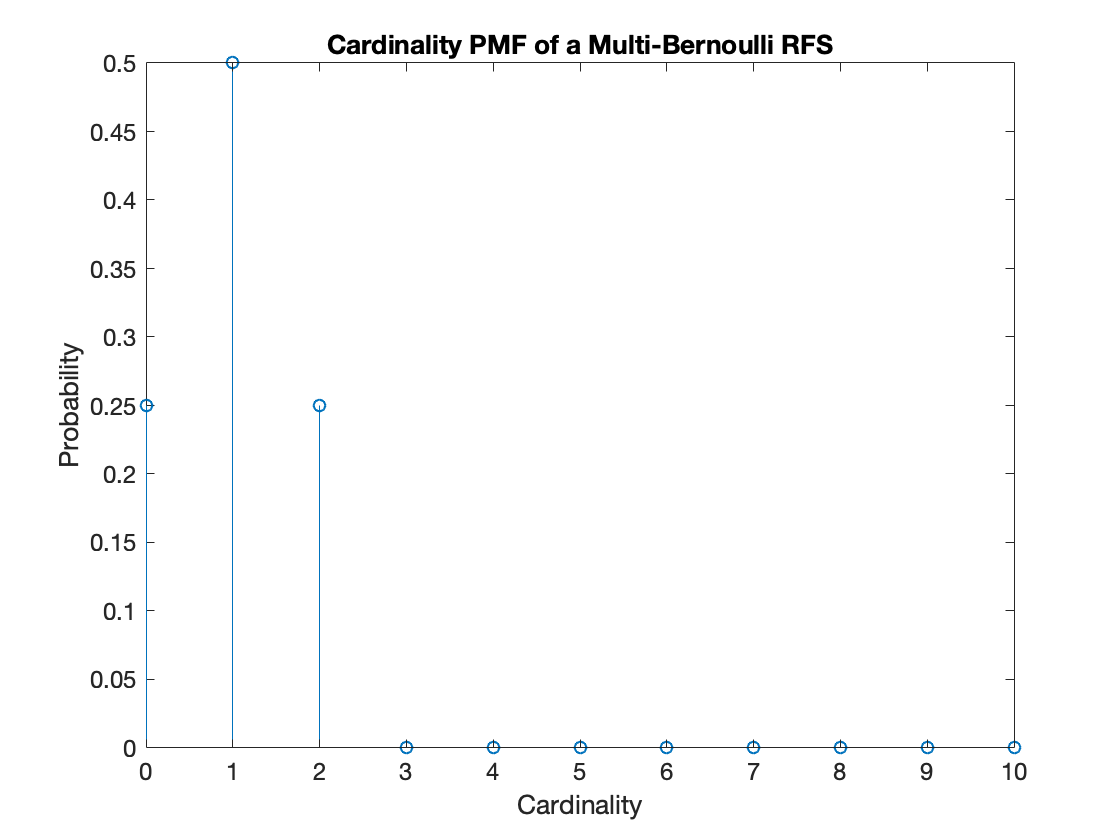


%multi-Bernoulli RFS
%2D
inputArg1{1} = [-1 1;-1 1];
inputArg1{2} = [-1 1;-1 1];

RFS = spatialDistribution(RFS,inputArg1);
M = 2;
r = ones(M,1)*0.5;
[RFS, multiBernoulliInstance] = multiBernoulliRFSs(RFS,r);
cardStemPlot(RFS, 0:10);

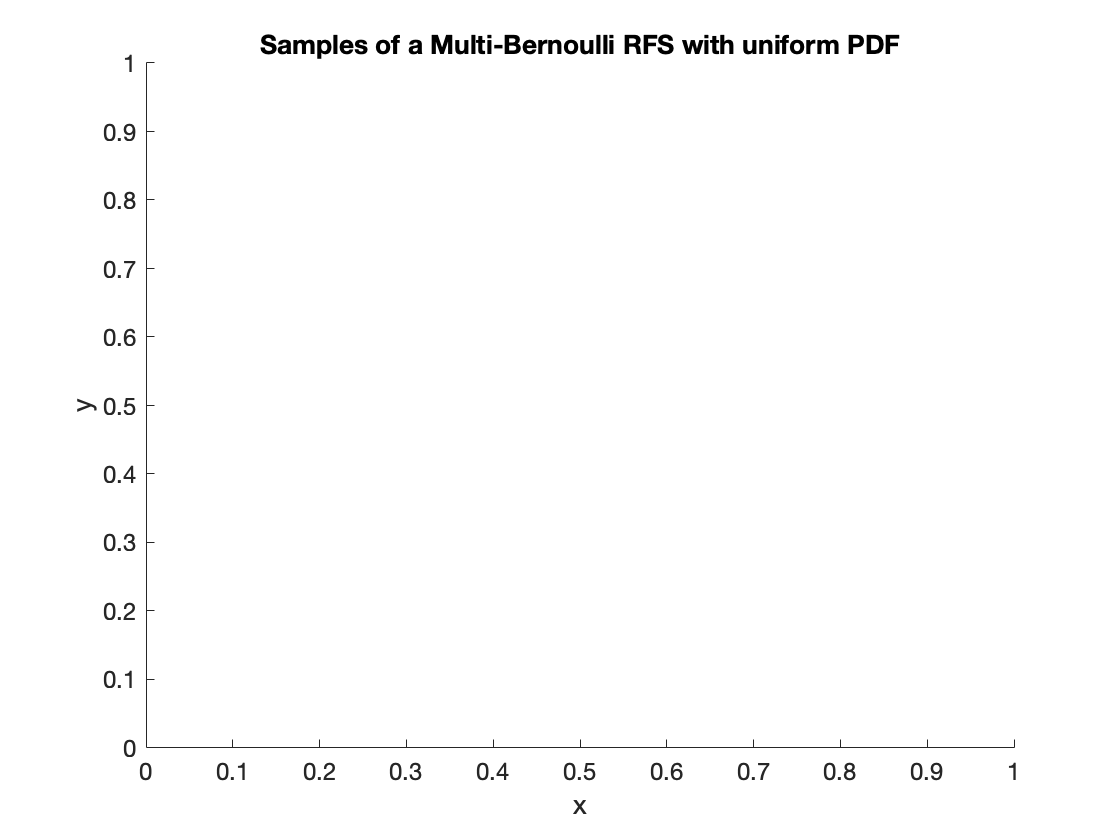

instance2Dplot(RFS,multiBernoulliInstance);

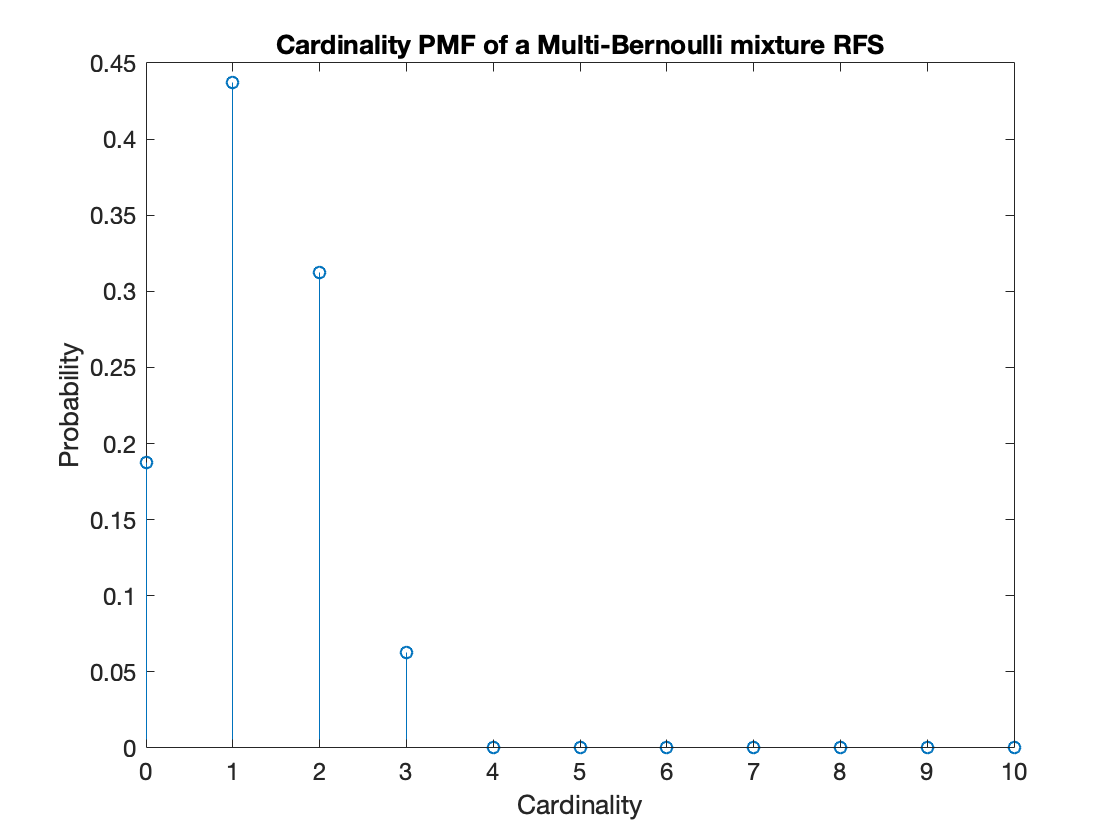


%multi-Bernoulli mixture RFS
%2D
inputArg1{1} = [-1 1;-1 1];
inputArg1{2} = [-1 1;-1 1];
inputArg1{3} = [-1 1;-1 1];

RFS = spatialDistribution(RFS,inputArg1);
M = [2,3];
p = [0.5 0.5];
r = cell(length(M),1);
r{1} = ones(M(1),1)*0.5;
r{2} = ones(M(2),1)*0.5;
[RFS, multiBernoulliMixtureInstance] = multiBernoulliMixtureRFSs(RFS,r,p);
cardStemPlot(RFS, 0:10);

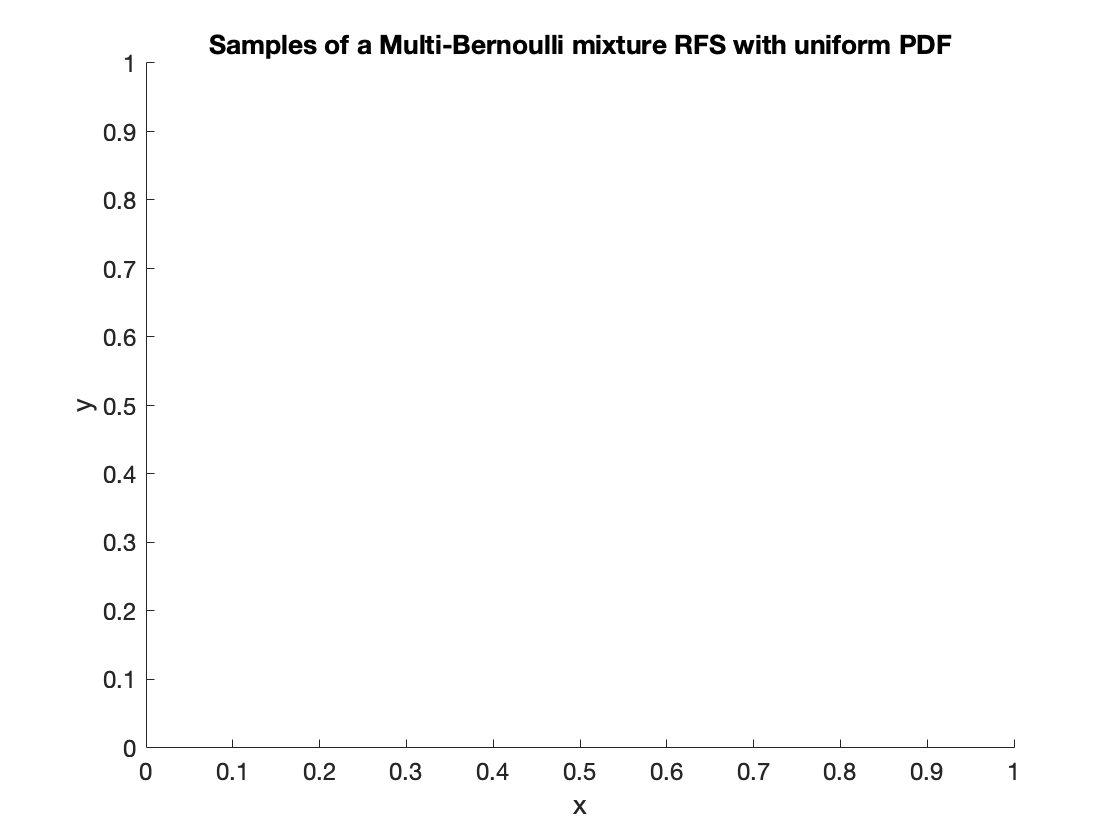

instance2Dplot(RFS,multiBernoulliMixtureInstance);

%% Gaussian distribution
%inputArg1{i} specifies the mean of multivariate Gaussian distribution
%components, a m length numeric vector, where m is the number of variables 
%in each component. 

%inputArg2{i} specifies the covariances of multivariate Gaussian
%distribution components, a m-by-m matrix.
clear

RFS = multiobjectProcess();

%Poisson RFS
%2D
inputArg1{1} = [0;0];
inputArg2{1} = eye(2);

RFS = spatialDistribution(RFS,inputArg1,inputArg2);
lambda = 2;
[RFS, PoissonInstance] = PoissonRFSs(RFS,lambda);
cardStemPlot(RFS, 0:10);

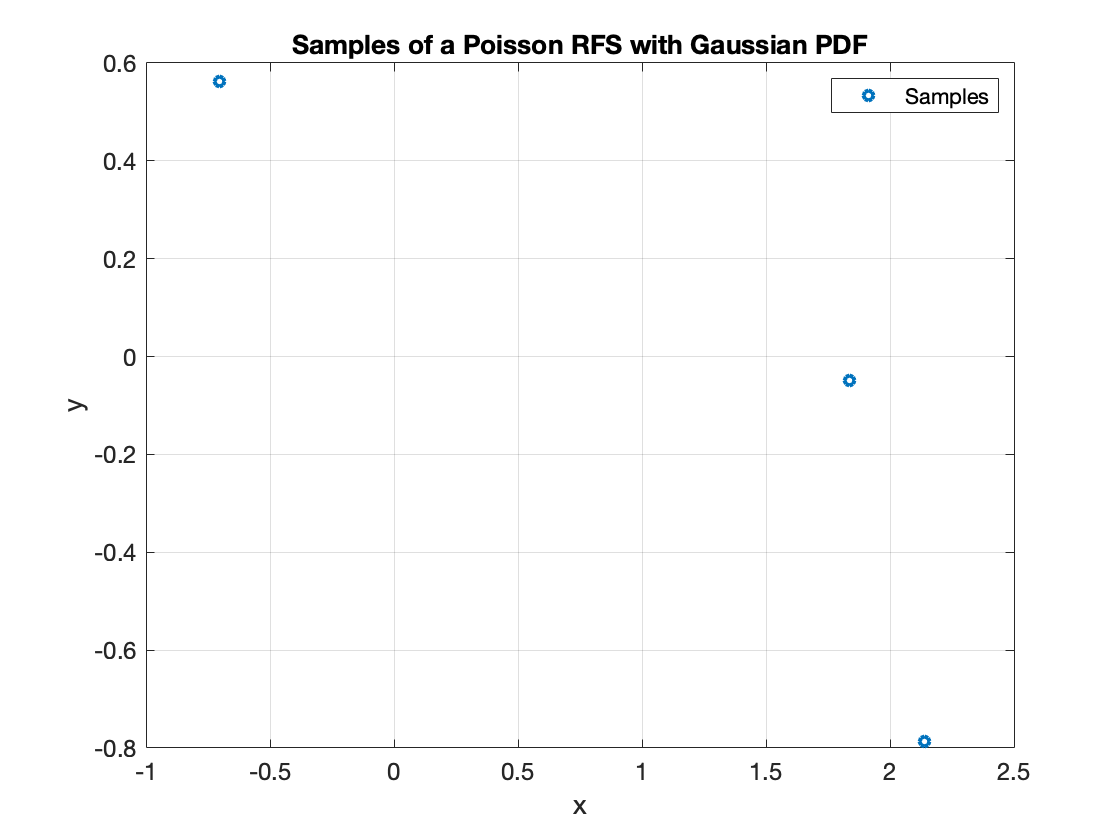

instance2Dplot(RFS,PoissonInstance);


%Bernoulli RFS
%2D
inputArg1{1} = [0;0];
inputArg2{1} = eye(2);

RFS = spatialDistribution(RFS,inputArg1,inputArg2);
r = 0.5;
[RFS, BernoulliInstance] = BernoulliRFSs(RFS,r);
cardStemPlot(RFS, 0:10);

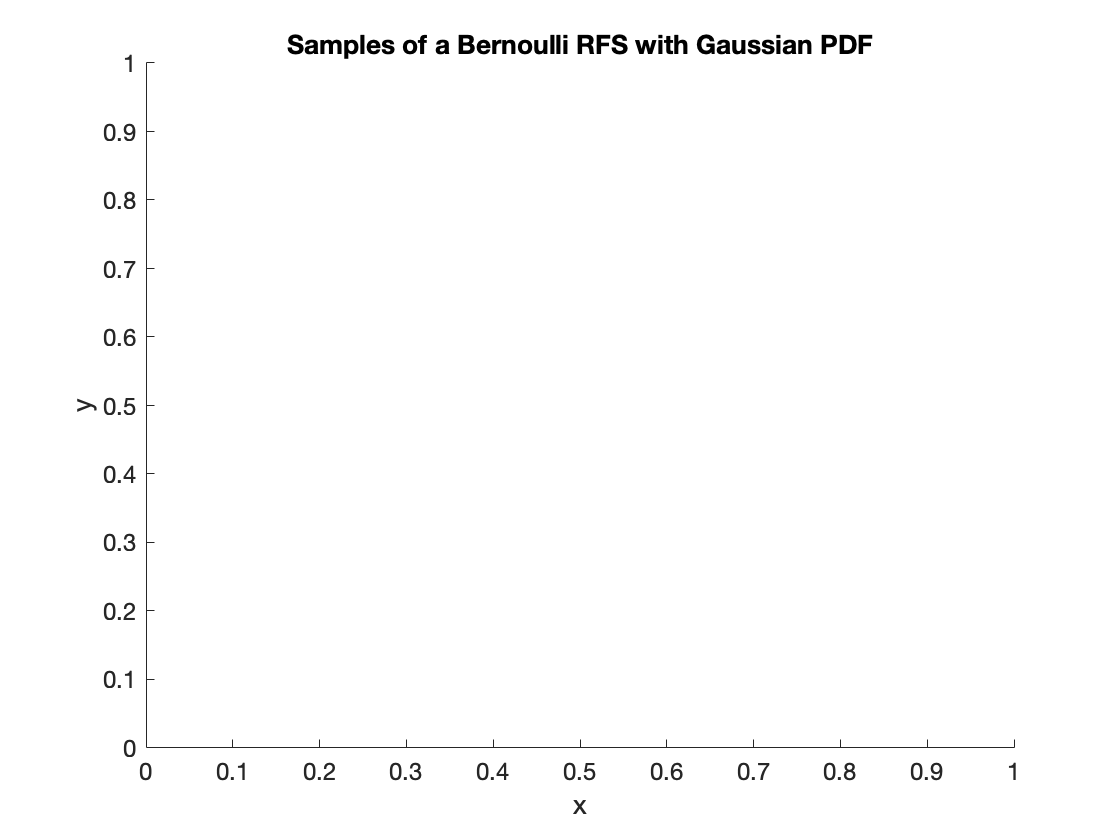

instance2Dplot(RFS,BernoulliInstance);


%multi-Bernoulli RFS
%2D
inputArg1{1} = [0;0];
inputArg2{1} = eye(2);
inputArg1{2} = [0;0];
inputArg2{2} = eye(2);

RFS = spatialDistribution(RFS,inputArg1,inputArg2);
M = 2;
r = ones(M,1)*0.5;
[RFS, multiBernoulliInstance] = multiBernoulliRFSs(RFS,r);
cardStemPlot(RFS, 0:10);

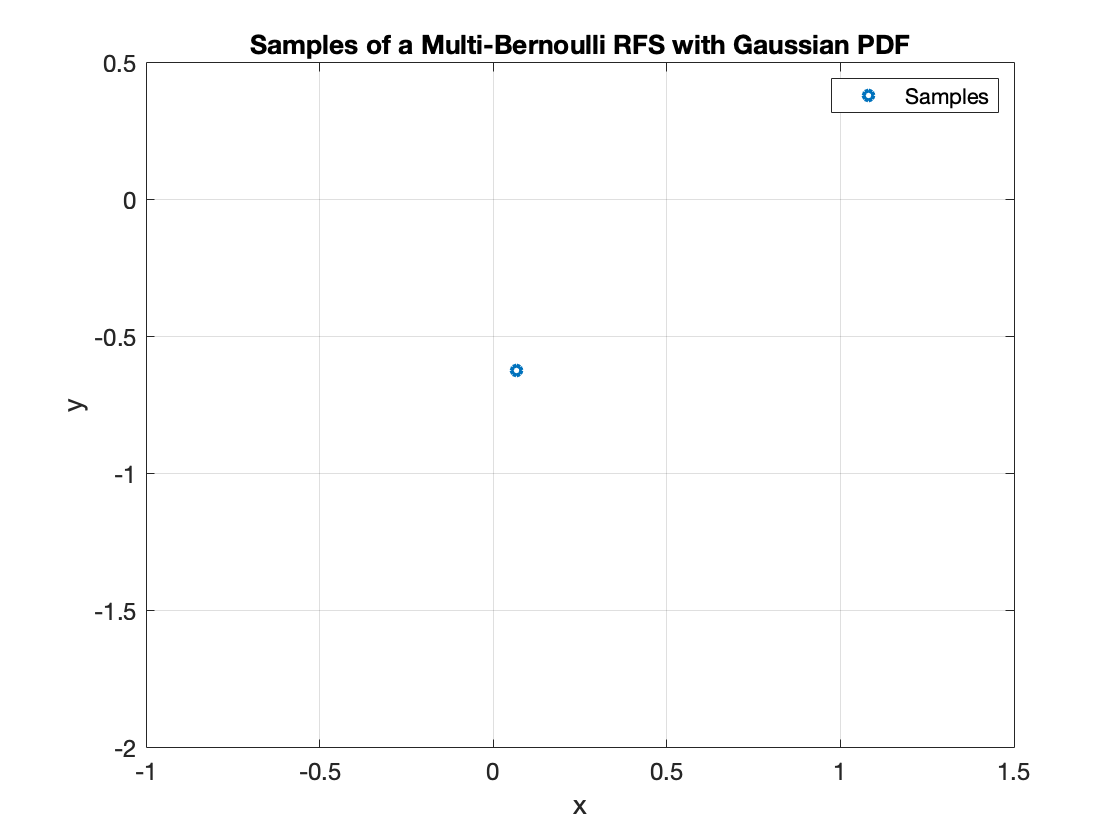

instance2Dplot(RFS,multiBernoulliInstance);


%multi-Bernoulli mixture RFS
%2D
inputArg1{1} = [0;0];
inputArg2{1} = eye(2);
inputArg1{2} = [0;0];
inputArg2{2} = eye(2);
inputArg1{3} = [0;0];
inputArg2{3} = eye(2);

RFS = spatialDistribution(RFS,inputArg1,inputArg2);
M = [2,3];
p = [0.5 0.5];
r = cell(length(M),1);
r{1} = ones(M(1),1)*0.5;
r{2} = ones(M(2),1)*0.5;
[RFS, multiBernoulliMixtureInstance] = multiBernoulliMixtureRFSs(RFS,r,p);
cardStemPlot(RFS, 0:10);

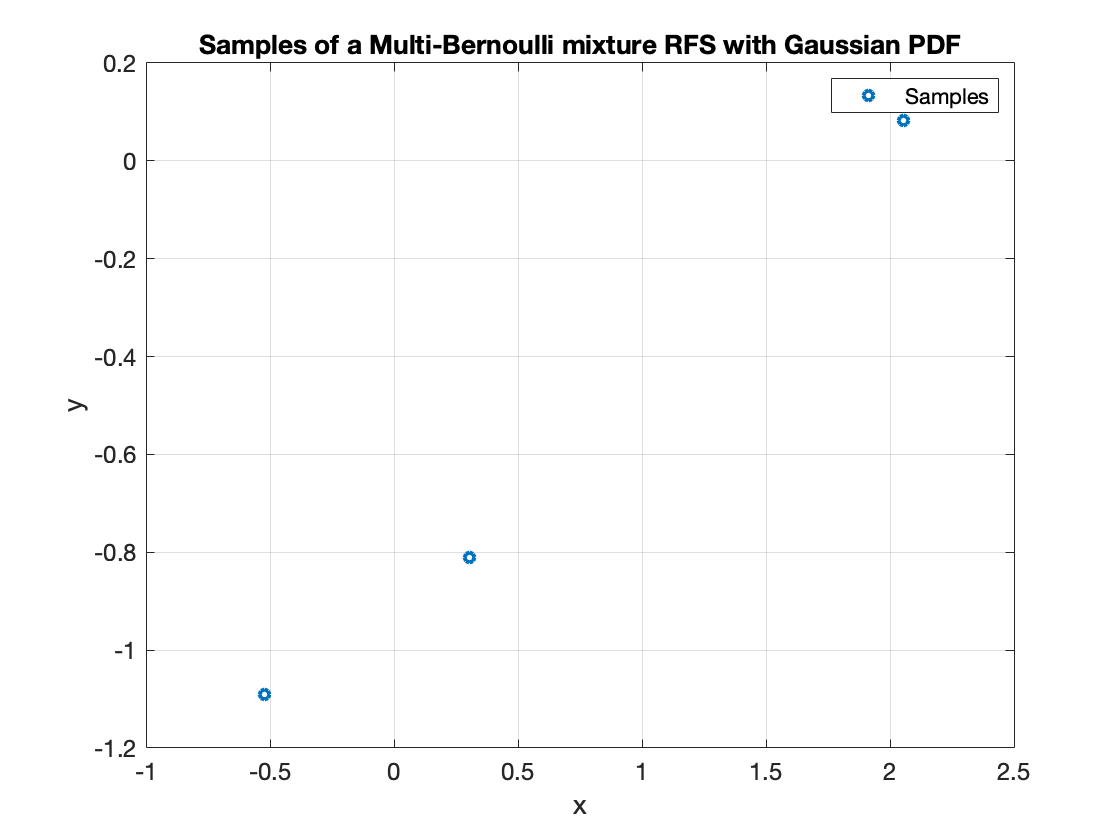

instance2Dplot(RFS,multiBernoulliMixtureInstance);

%% Gaussian mixture distribution
%inputArg1{i} specifies the means of multivariate Gaussian distribution
%components, a k-by-m numeric matrix, where k is the number of components 
%and m is the number of variables in each component. inputArg1{i}(i,:) is
%the mean of component i.

%inputArg2{i} specifies the covariances of multivariate Gaussian
%distribution components, either a m-by-m-by-k array, where inputArg2{i}(:,:,i) 
%is the covariance matrix of component i, or a m-by-m array, where covaraince 
%can be the same across components.

%inputArg3{i} specifies the mixing proportions of mixture components, 
%specified as a numeric vector with length k.
clear

RFS = multiobjectProcess();

%Poisson RFS
%2D
inputArg1{1} = [0 0;1 1];
inputArg2{1} = eye(2);      
inputArg3{1} = [0.5 0.5];

RFS = spatialDistribution(RFS,inputArg1,inputArg2,inputArg3);
lambda = 2;
[RFS, PoissonInstance] = PoissonRFSs(RFS,lambda);
cardStemPlot(RFS, 0:10);

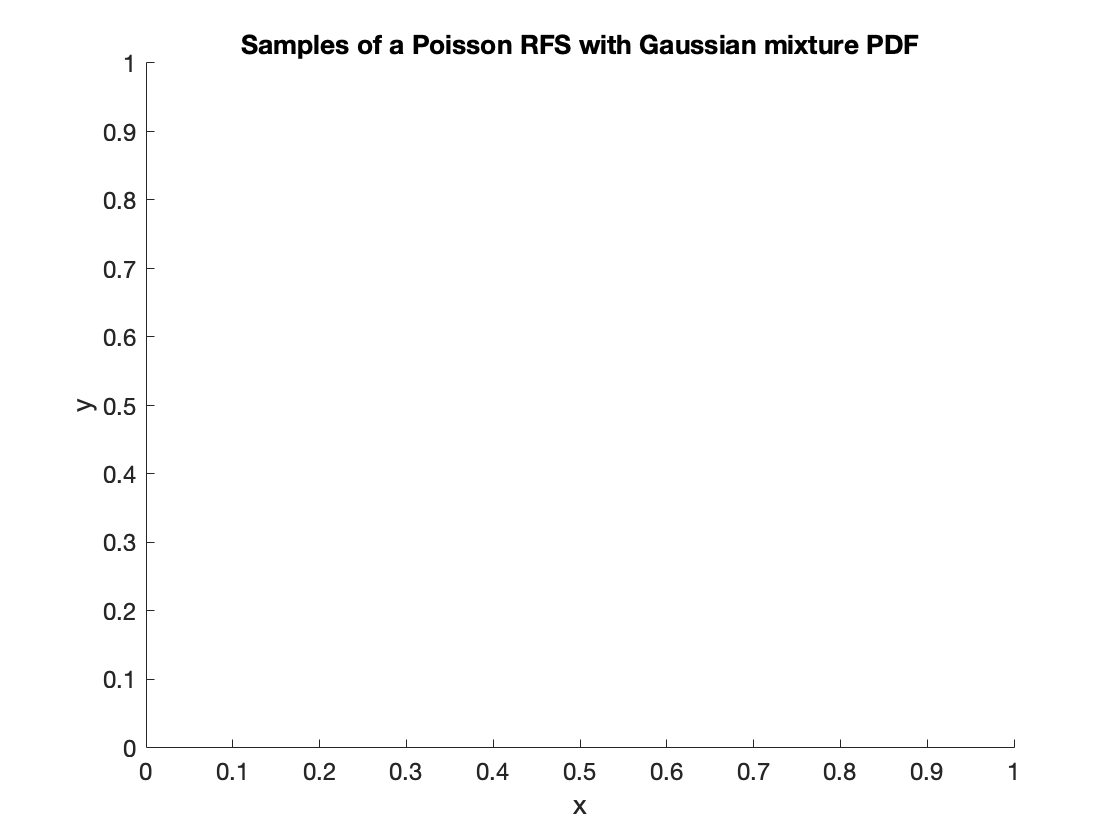

instance2Dplot(RFS,PoissonInstance);


%Bernoulli RFS
%2D
inputArg1{1} = [0 0;1 1];
inputArg2{1} = eye(2);      
inputArg3{1} = [0.5 0.5];

RFS = spatialDistribution(RFS,inputArg1,inputArg2,inputArg3);
r = 0.5;
[RFS, BernoulliInstance] = BernoulliRFSs(RFS,r);
cardStemPlot(RFS, 0:10);

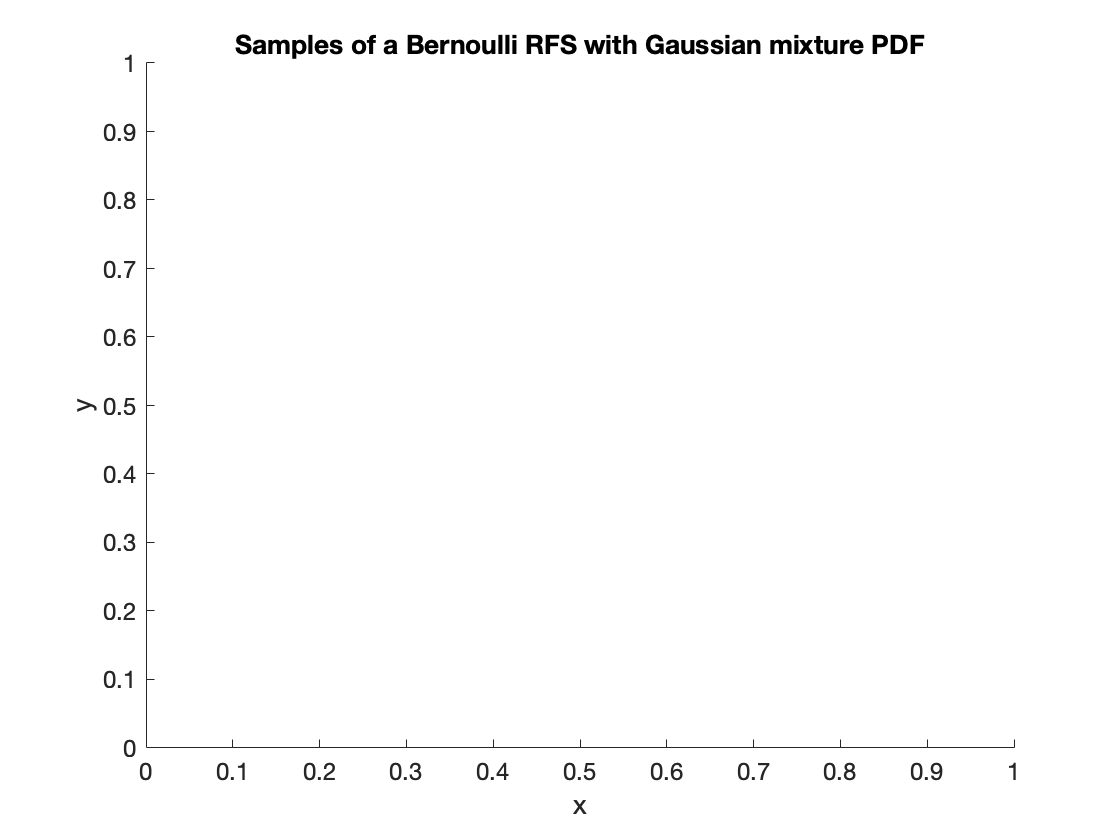

instance2Dplot(RFS,BernoulliInstance);


%multi-Bernoulli RFS
%2D
inputArg1{1} = [0 0;1 1];
inputArg2{1} = eye(2);      
inputArg3{1} = [0.5 0.5];
inputArg1{2} = [0 0;1 1];
inputArg2{2} = eye(2);      
inputArg3{2} = [0.5 0.5];

RFS = spatialDistribution(RFS,inputArg1,inputArg2,inputArg3);
M = 2;
r = ones(M,1)*0.5;
[RFS, multiBernoulliInstance] = multiBernoulliRFSs(RFS,r);
cardStemPlot(RFS, 0:10);

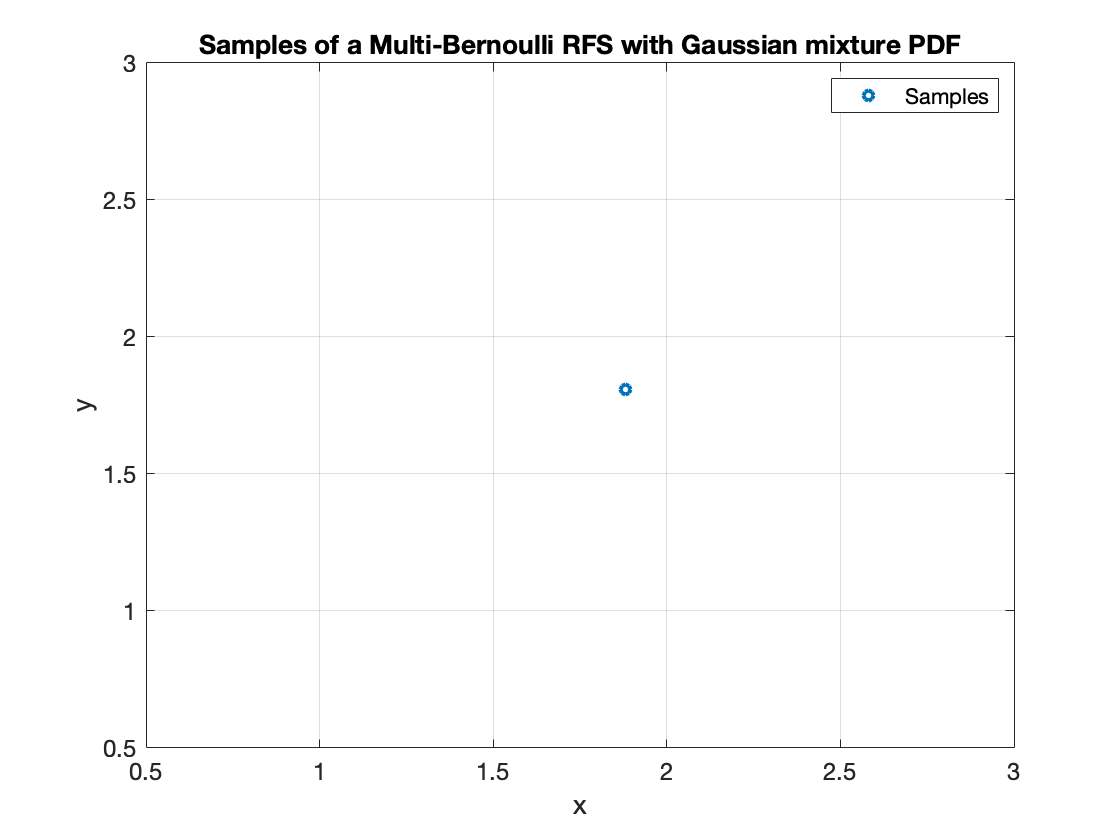

instance2Dplot(RFS,multiBernoulliInstance);


%multi-Bernoulli mixture RFS
%2D
inputArg1{1} = [0 0;1 1];
inputArg2{1} = eye(2);      
inputArg3{1} = [0.5 0.5];
inputArg1{2} = [0 0;1 1];
inputArg2{2} = eye(2);      
inputArg3{2} = [0.5 0.5];
inputArg1{3} = [0 0;1 1];
inputArg2{3} = eye(2);      
inputArg3{3} = [0.5 0.5];

RFS = spatialDistribution(RFS,inputArg1,inputArg2,inputArg3);
M = [2,3];
p = [0.5 0.5];
r = cell(length(M),1);
r{1} = ones(M(1),1)*0.5;
r{2} = ones(M(2),1)*0.5;
[RFS, multiBernoulliMixtureInstance] = multiBernoulliMixtureRFSs(RFS,r,p);
cardStemPlot(RFS, 0:10);

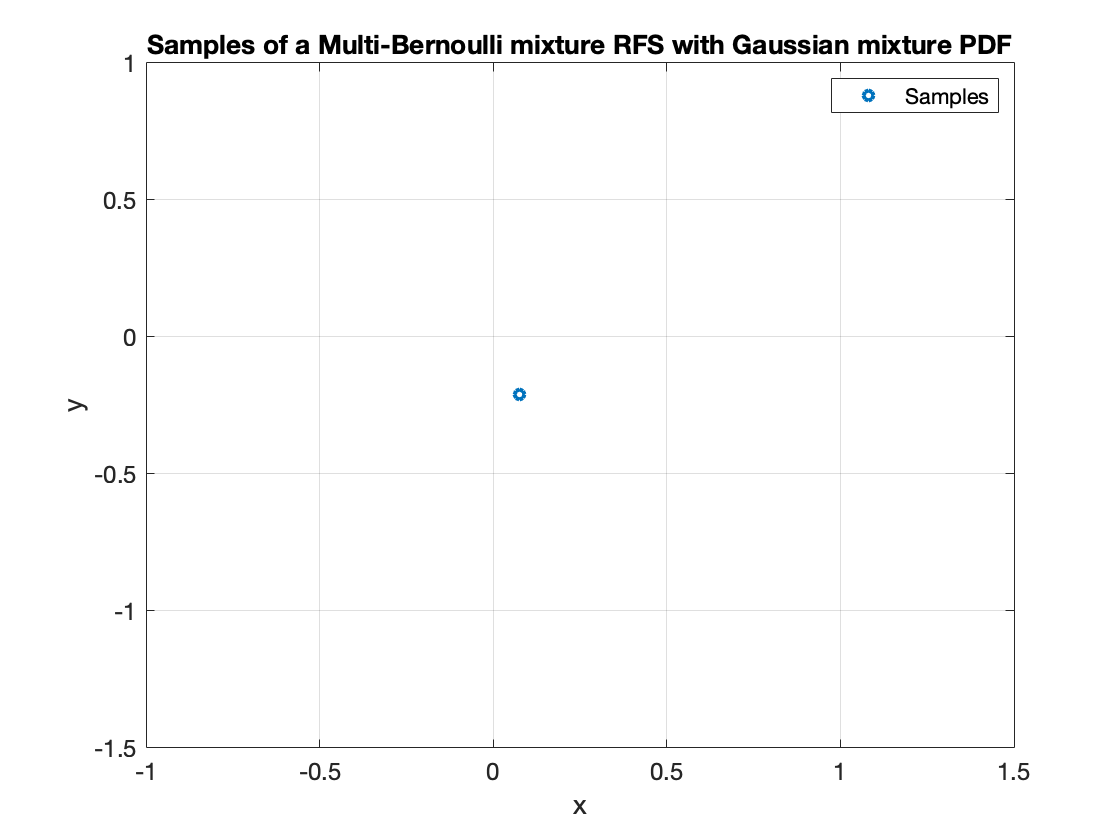

instance2Dplot(RFS,multiBernoulliMixtureInstance);

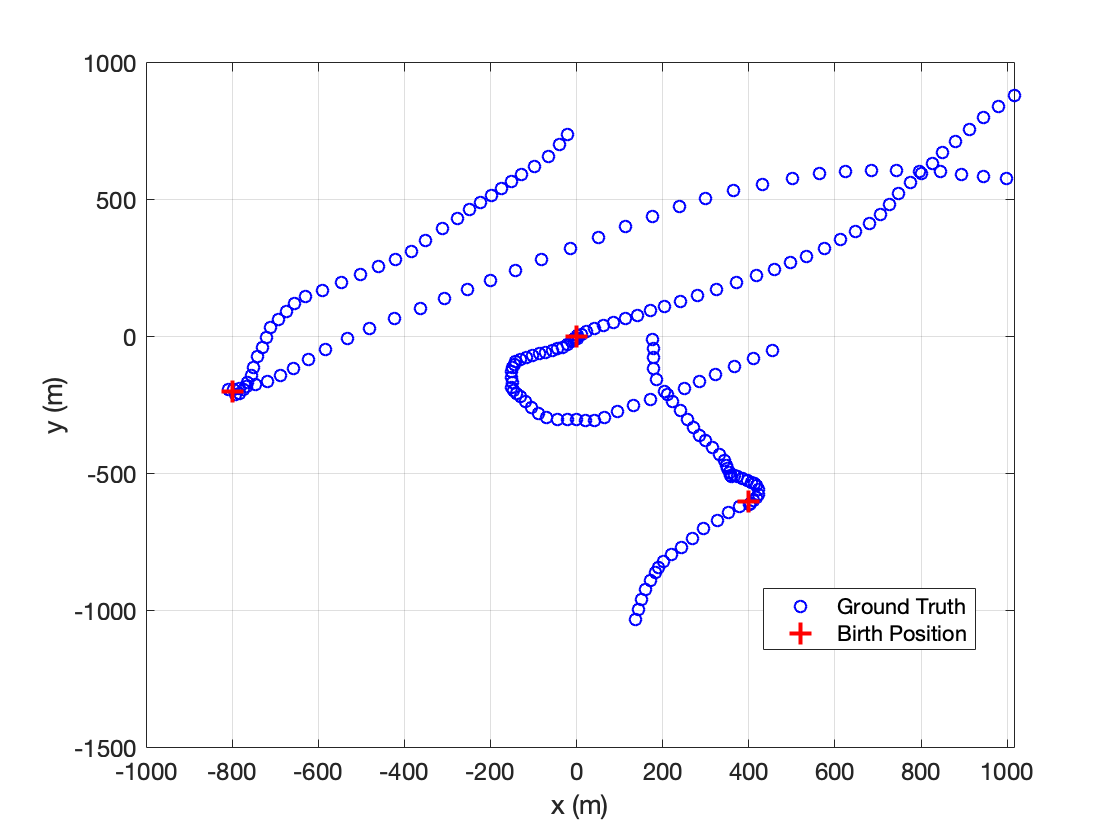

%% Generate object tracks
%draw samples from RFS of objects (dynamic equations) to simulate object 
%trajectories. Assume that a 2D measurement model is used.
%Choose object detection probability
%% Generate object tracks
%draw samples from RFS of objects (dynamic equations) to simulate object 
%trajectories. Assume that a 2D measurement model is used.
%Choose object detection probability
clear

%Choose object survival probability
P_S = 0.99;
%Choose range of surveillance area
range_c = [-1000 1000;-1000 1000];
sensor_model = modelgen.sensormodel([],[],range_c);

%Create linear motion model
T = 1;
sigma_q = 5;
motion_model = motionmodel.cvmodel(T,sigma_q);

%Create linear measurement model
sigma_r = 10;
meas_model = measmodel.cvmeasmodel(sigma_r);

%Create ground truth model
nbirths = 3;
K = 100;
birth_model = repmat(struct('w',log(0.03),'x',[],'P',100*eye(motion_model.d)),[1,nbirths]);
birth_model(1).x  = [ 0; 0; 0; -10 ];
birth_model(2).x  = [ 400; -600; -10; 5 ];
birth_model(3).x  = [ -800; -200; 20; -5 ];

%Generate object tracks
[object_tracks] = trackgen(K,meas_model,motion_model,sensor_model,birth_model,P_S);

%Plot trajectories
trajectory = [object_tracks.x];

figure
box on
grid on

hold on

plot(trajectory(1,:), trajectory(2,:), 'bo', 'Linewidth', 1);
plot(birth_model(1).x(1),birth_model(1).x(2),'r+', 'Markersize',10, 'Linewidth',2);
plot(birth_model(2).x(1),birth_model(2).x(2),'r+', 'Markersize',10, 'Linewidth',2);
plot(birth_model(3).x(1),birth_model(3).x(2),'r+', 'Markersize',10, 'Linewidth',2);

xlabel('x (m)'); ylabel('y (m)')
legend('Ground Truth','Birth Position','Location', 'best')
set(gca,'FontSize',12) 